##  Electromagnetic Field Theory Experiment One

Reporter: Gan Yuhao Student ID: 12211629

**Scenario One:** The electric field distribution of two equal and like point charges

    1. Matlab Source Code

1)Calculate the appropriate range of the field

clear;                      %清空内存中所有变量
clc;                        %清空命令窗口中的内容
k = 9e9;                    %设置静电力恒量
Q1 = 1e-9;                  %设置电荷1的电量
Q2 = 1e-9;                  %设置电荷2的电量
xm = 0.05;                  %设置场域中x方向的范围
ym = 0.05;                  %设置场域中y方向的范围
x = linspace(-xm,xm,50);    %将x轴分为50等分
y = linspace(-ym,ym,50);    %将y轴分为50等分
[X,Y] = meshgrid(x,y);      %形成场域中各点的坐标
R1 = sqrt((X+0.01).^2+Y.^2);%计算场域中各点到点电荷1的距离
R2 = sqrt((X-0.01).^2+Y.^2);%计算场域中各点到点电荷2的距离

2)Calculate and plot the distribution of electric potential within the field

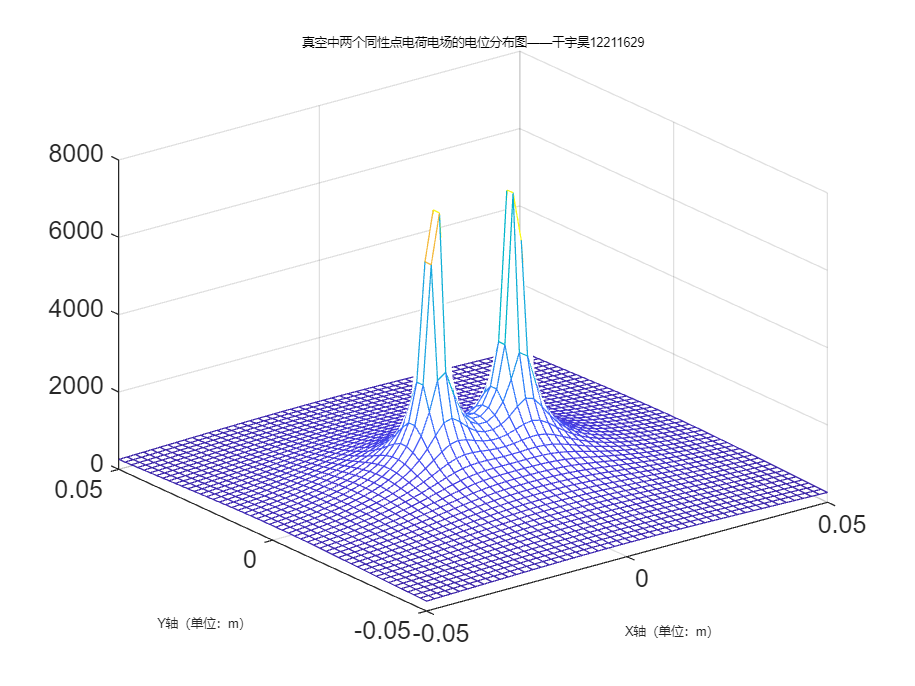

V = k*Q1./R1+k*Q2./R2;      %计算场域中各点的电位
mesh(X,Y,V);                %绘制出电位的分布图
hold on;                    %绘出图形标题
title('真空中两个同性点电荷电场的电位分布图——干宇昊12211629','FontSize',5); %绘制出图形标题
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: The potential is diffused from the two charge peaks to the surrounding area, and the farther the distance is, the lower the potential is

3）Plot the distribution of equipotential lines within the field

Vmax = max(max(V))%查看电位最大值

Vmax = 7.3557e+03

Vmin = min(min(V))%查看电位最小值

Vmin = 255.7896

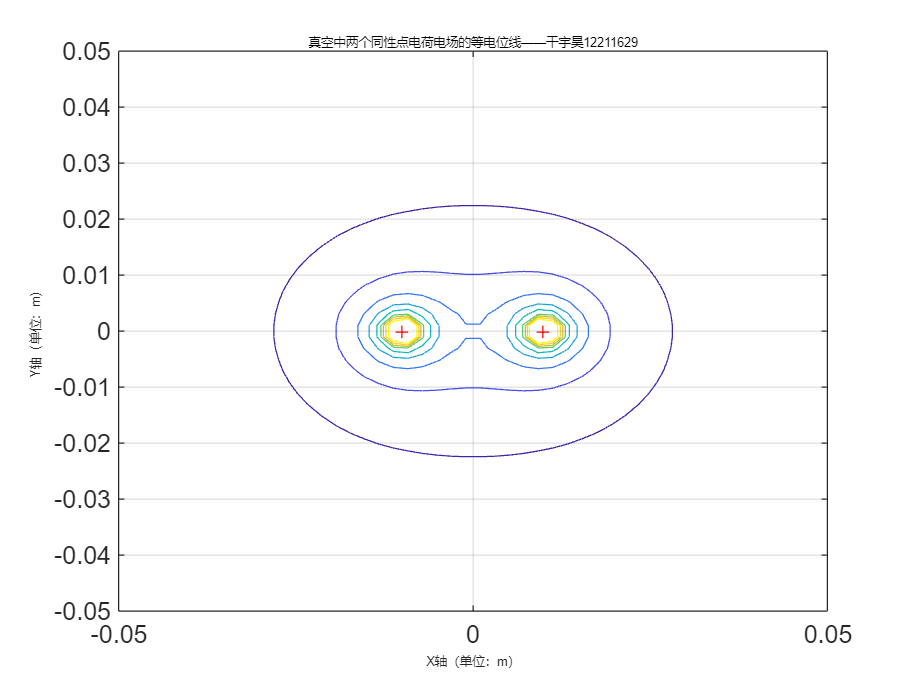

Vmin = 200;%设置等电位族的最小电位值
Vmax = 5000;%设置等电位族的最大电位值
Veq = linspace(Vmin,Vmax,10);%设置10条等位线的电位值
figure;
contour(X,Y,V,Veq);%绘制10条等势线
grid on;
hold on;
plot(-0.01,0,'r+','MarkerSize',5);%画出电荷1
plot(0.01,0,'r+','MarkerSize',5);%画出电荷2
title('真空中两个同性点电荷电场的等电位线——干宇昊12211629','FontSize',5);
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: The electric potential spreads from the two charges as peaks. The farther from the charges, the lower the potential.

4）Plot the distribution of equipotential lines and electric field lines (represented by smooth continuous curves) in the field

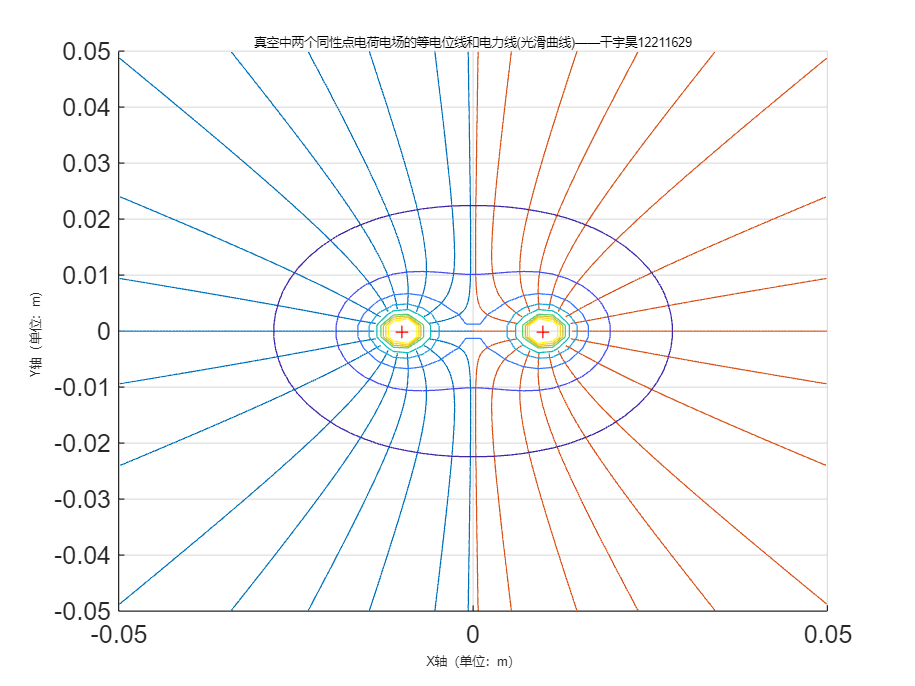

[Ex,Ey] = gradient(-V);%计算场域各点的电场强度的两个分量
del_theta = 20;%设置相邻电力线间的角度差;
theta = (0:del_theta:360).*pi/180;%生成电力线的弧度值;
xs1 = -0.01-0.004*cos(theta);%生成电力线起点的x轴坐标;
xs2 = 0.01+0.004*cos(theta);
ys1= 0.004*sin(theta);%生成电力线起点的y轴坐标;
ys2= 0.004*sin(theta);
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,Ex,Ey,xs2,ys2);%生成电力线;
grid on;
hold on;
contour(X,Y,V,Veq);
plot(-0.01,0,'r+','MarkerSize',5);%画出电荷1
plot(0.01,0,'r+','MarkerSize',5);%画出电荷2
title('真空中两个同性点电荷电场的等电位线和电力线(光滑曲线)——干宇昊12211629','FontSize',5);
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: The electric field line is perpendicular to the equipotential line and away from the charge

5）Plot the distribution of equipotential lines and electric field lines (represented by normalized arrows) in the field

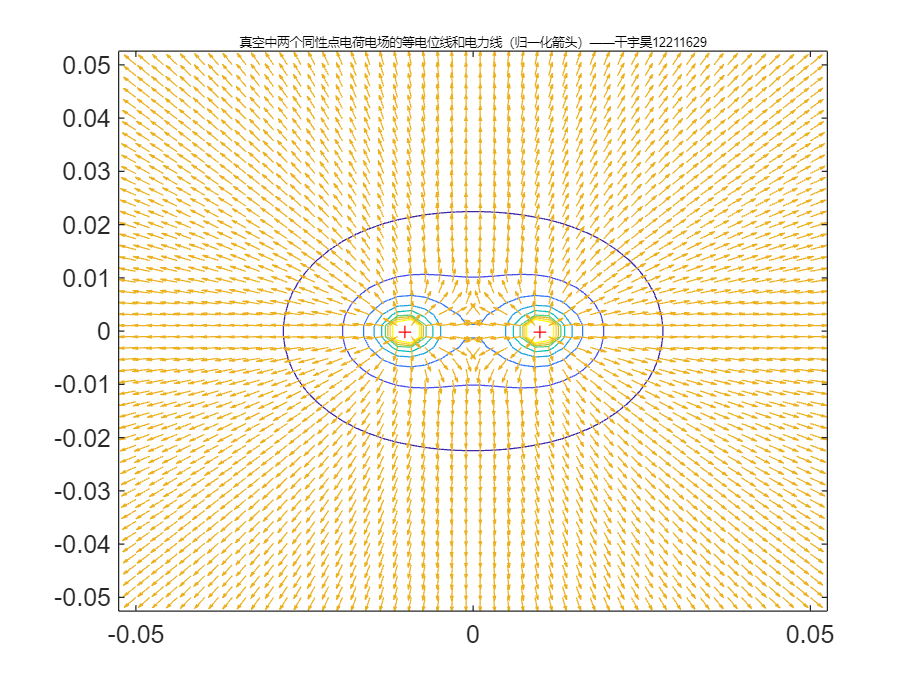

E = sqrt(Ex.^2+Ey.^2);%计算场域各点的电场强度的幅值
Ex = Ex./E;%归一化电场强度值（即使各点场强幅值为1
Ey = Ey./E;
figure;
contour(X,Y,V,Veq);
hold on;
plot(-0.01,0,'r+','MarkerSize',5);%画出电荷1
hold on;
plot(0.01,0,'r+','MarkerSize',5);%画出电荷2
hold on;
quiver(X,Y,Ex,Ey);%用归一化箭头表示场域各点电场强度的方向
title('真空中两个同性点电荷电场的等电位线和电力线（归一化箭头）——干宇昊12211629','FontSize',5);

Analysis: The electric field line is perpendicular to the equipotential line and away from the charge

**Scenario Two**: The electric field distribution of two equal and opposite point charges

     1. Matlab Source Code

1)Calculate the appropriate range of the field

clear;                      %清空内存中所有变量
clc;                        %清空命令窗口中的内容
k = 9e9;                    %设置静电力恒量
Q1 = 5e-9;                  %设置电荷1的电量
Q2 = -5e-9;                 %设置电荷2的电量
xm = 4;                  %设置场域中x方向的范围
ym = 4;                  %设置场域中y方向的范围
x = linspace(-xm,xm,50);   %将x轴分为50等分
y = linspace(-ym,ym,50);   %将y轴分为50等分
[X,Y] = meshgrid(x,y);     %形成场域中各点的坐标
R1 = sqrt((X+2).^2+Y.^2);%计算场域中各点到点电荷1的距离
R2 = sqrt((X-2).^2+Y.^2);%计算场域中各点到点电荷2的距离

2)Calculate the appropriate range of the field

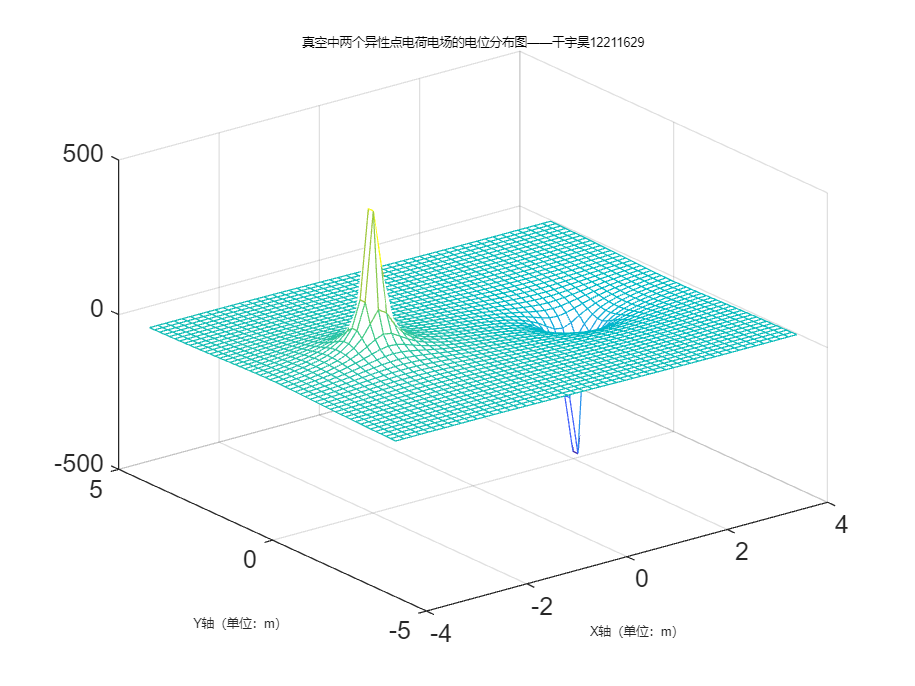

V = k*Q1./R1+k*Q2./R2;%计算场域中各点的电位
V1 = k*Q1./R2+k*Q2./R1;
figure;
mesh(X,Y,V);                %绘制出电位的分布图
hold on;                    %绘出图形标题
title('真空中两个异性点电荷电场的电位分布图——干宇昊12211629','FontSize',5); %绘制出图形标题
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: The potential of the positive side is positive, and the potential of the negative side is negative

3）Calculate the appropriate range of the field

Vmax = max(max(V))%查看电位最大值

Vmax = 481.9189

Vmin = min(min(V))%查看电位最小值

Vmin = -481.9189

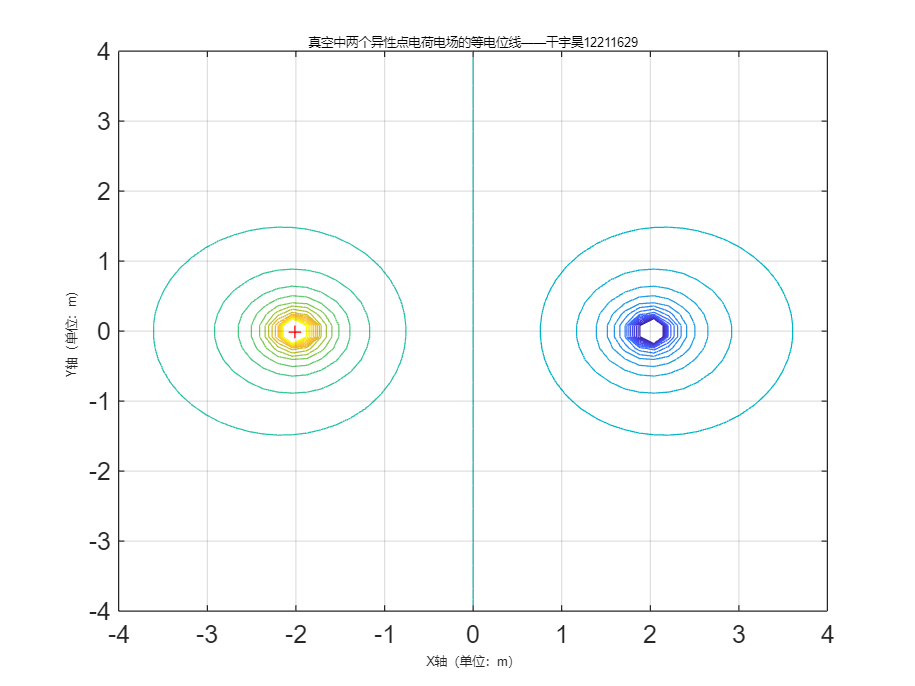

Vmin = -300;%设置等电位族的最小电位值
Vmax = 300;%设置等电位族的最大电位值
Veq = linspace(Vmin,Vmax,31);%设置31条等位线的电位值
V0 = 0;
figure;
contour(X,Y,V,Veq);%绘制30条等势线
grid on;
hold on;
plot(-2,0,'+r','MarkerSize',5);%画出电荷1
plot(2,0,'-r','MarkerSize',5);%画出电荷2
title('真空中两个异性点电荷电场的等电位线——干宇昊12211629','FontSize',5);
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: electric potential being positive on one side and negative on the other, with equipotential lines being symmetric around the y-axis.

4）Plot the distribution of equipotential lines and electric field lines (represented by smooth continuous curves) in the field

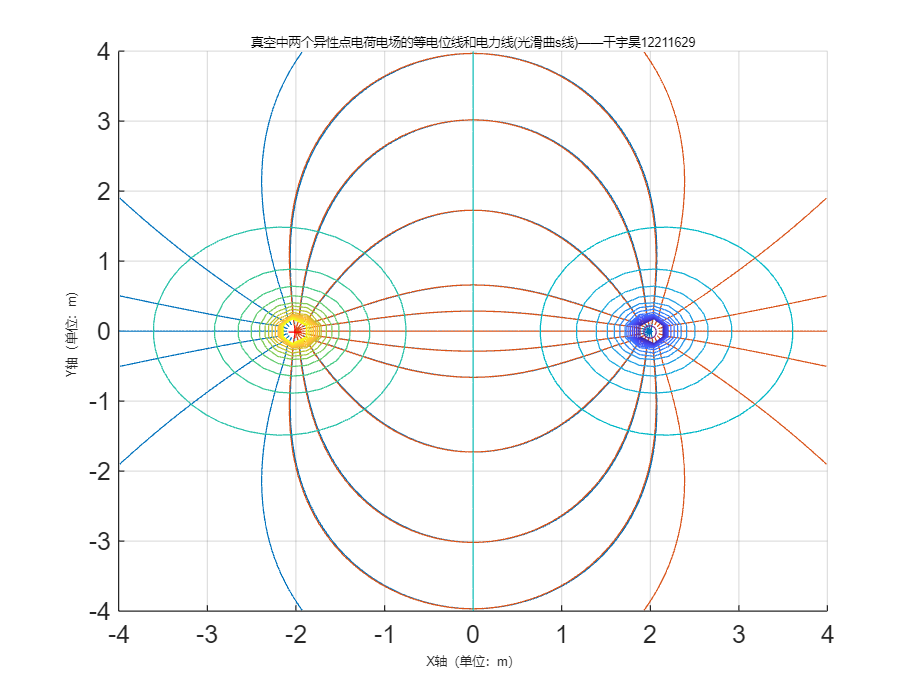

[Ex,Ey] = gradient(-V);%计算场域各点的电场强度的两个分量
[Ex1,Ey1] = gradient(-V1);
del_theta = 20;%设置相邻电力线间的角度差;
theta = (0:del_theta:360).*pi/180;%生成电力线的弧度值;
xs1 = -2-0.1*cos(theta);%生成电力线起点的x轴坐标;
xs2 = 2-0.1*cos(theta);
ys1= 0.1*sin(theta);%生成电力线起点的y轴坐标;
ys2= 0.1*sin(theta);
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,Ex1,Ey1,xs2,ys2);
grid on;
hold on;
contour(X,Y,V,Veq);
plot(-2,0,'+r','MarkerSize',5);%画出电荷1
plot(2,0,'o','MarkerSize',5);%画出电荷2
title('真空中两个异性点电荷电场的等电位线和电力线(光滑曲s线)——干宇昊12211629','FontSize',5);
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: The electric field line points from positive charge to negative charge

5）Plot the distribution of equipotential lines and electric field lines (represented by smooth continuous curves) in the field

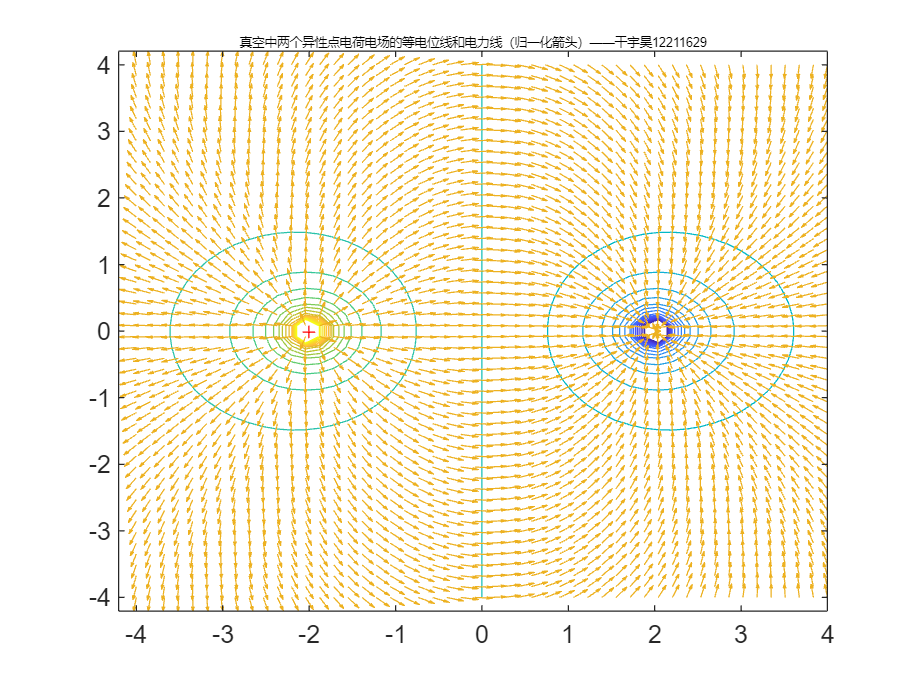

E = sqrt(Ex.^2+Ey.^2);%计算场域各点的电场强度的幅值
Ex = Ex./E;%归一化电场强度值（即使各点场强幅值为1
Ey = Ey./E;
figure;
contour(X,Y,V,Veq);
hold on;
plot(-2,0,'+r','MarkerSize',5);%画出电荷1
hold on;
plot(2,0,'-r','MarkerSize',5);%画出电荷2
hold on;
quiver(X,Y,Ex,Ey);%用归一化箭头表示场域各点电场强度的方向
title('真空中两个异性点电荷电场的等电位线和电力线（归一化箭头）——干宇昊12211629','FontSize',5);

Analysis: The electric field line points from positive charge to negative charge

**Scenario Three**: The electric field distribution of three equal and like charges placed at the vertices of an equilateral triangle

- Matlab Source Code

1) Calculate the appropriate range of the field

clear;                      %清空内存中所有变量
clc;                        %清空命令窗口中的内容
k = 9e9;                    %设置静电力恒量
Q = 8e-9;                  %设置电荷1的电量
xm = 5;                  %设置场域中x方向的范围
ym = 5;                  %设置场域中y方向的范围
x = linspace(-xm,xm,50);   %将x轴分为50等分
y = linspace(-ym,ym,50);   %将y轴分为50等分
[X,Y] = meshgrid(x,y);     %形成场域中各点的坐标
R1 = sqrt((X+sqrt(3)).^2+(Y+1).^2);%计算场域中各点到点电荷1的距离
R2 = sqrt((X-sqrt(3)).^2+(Y+1).^2);%计算场域中各点到点电荷2的距离
R3 = sqrt((X).^2+(Y-2).^2);%计算场域中各点到点电荷3的距离

2)Calculate and plot the distribution of electric potential within the field

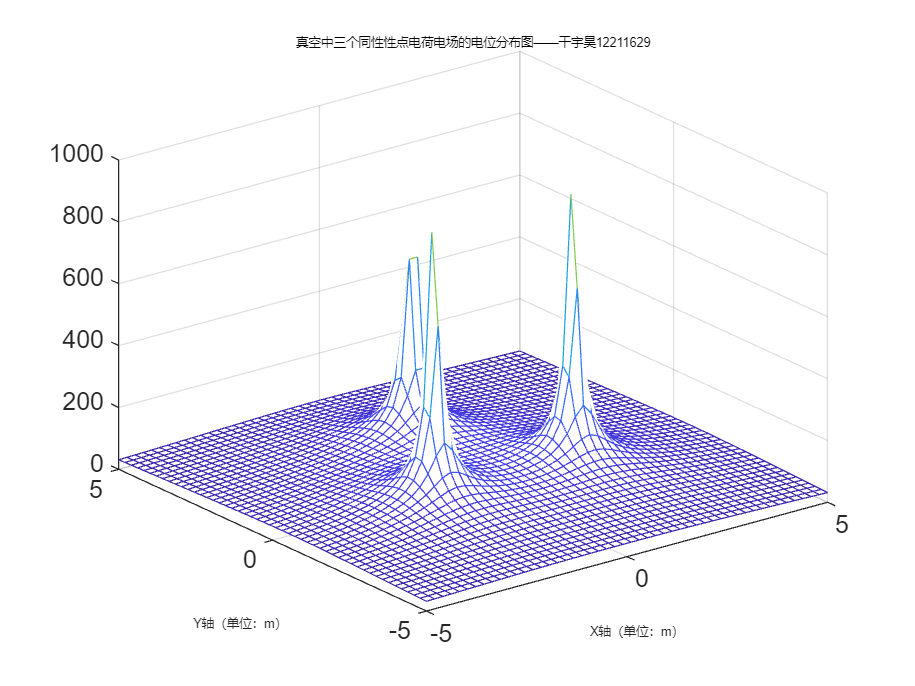

V = k*Q./R1+k*Q./R2+k*Q./R3;%计算场域中各点的电位
figure;
mesh(X,Y,V);                %绘制出电位的分布图
hold on;                    %绘出图形标题
title('真空中三个同性性点电荷电场的电位分布图——干宇昊12211629','FontSize',5); %绘制出图形标题
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: The electric potential spreads from the two charges as peaks. The farther from the charges, the lower the potential.

3）Plot the distribution of equipotential lines within the field

Vmax = max(max(V))%查看电位最大值

Vmax = 923.5087

Vmin = min(min(V))%查看电位最小值

Vmin = 30.8704

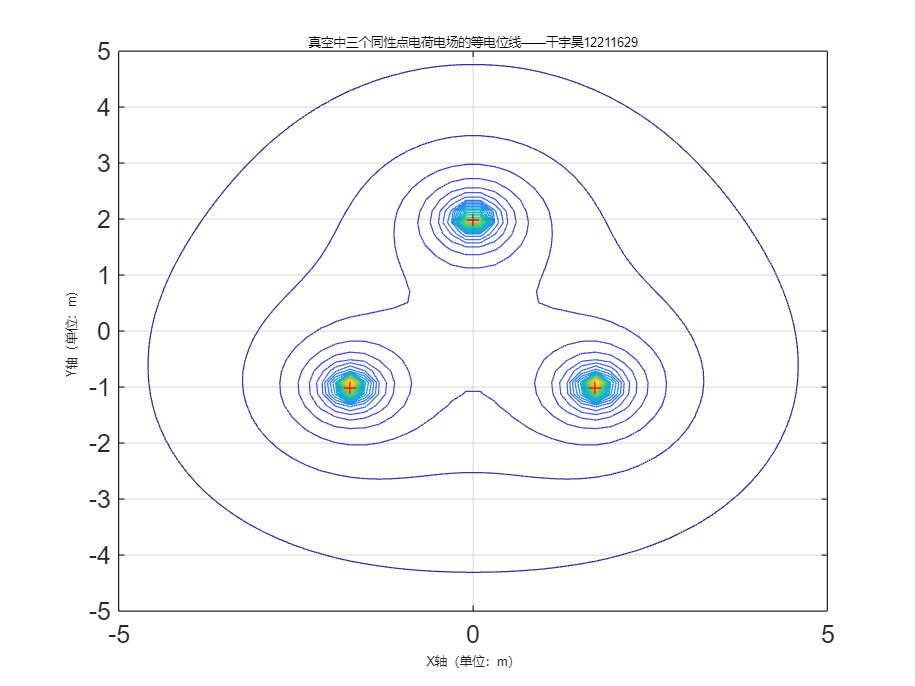

Vmin = 50;%设置等电位族的最小电位值
Vmax = 900;%设置等电位族的最大电位值
Veq = linspace(Vmin,Vmax,31);%设置31条等位线的电位值
V0 = 0;
figure;
contour(X,Y,V,Veq);%绘制30条等势线
grid on;
hold on;
plot(-sqrt(3),-1,'+r','MarkerSize',5);%画出电荷1
plot(sqrt(3),-1,'+r','MarkerSize',5);%画出电荷2
plot(0,2,'+r','MarkerSize',5);%画出电荷3
title('真空中三个同性点电荷电场的等电位线——干宇昊12211629','FontSize',5);
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: 120 degree rotation symmetry of equipotential line

4）Plot the distribution of equipotential lines and electric field lines (represented by smooth continuous curves) in the field

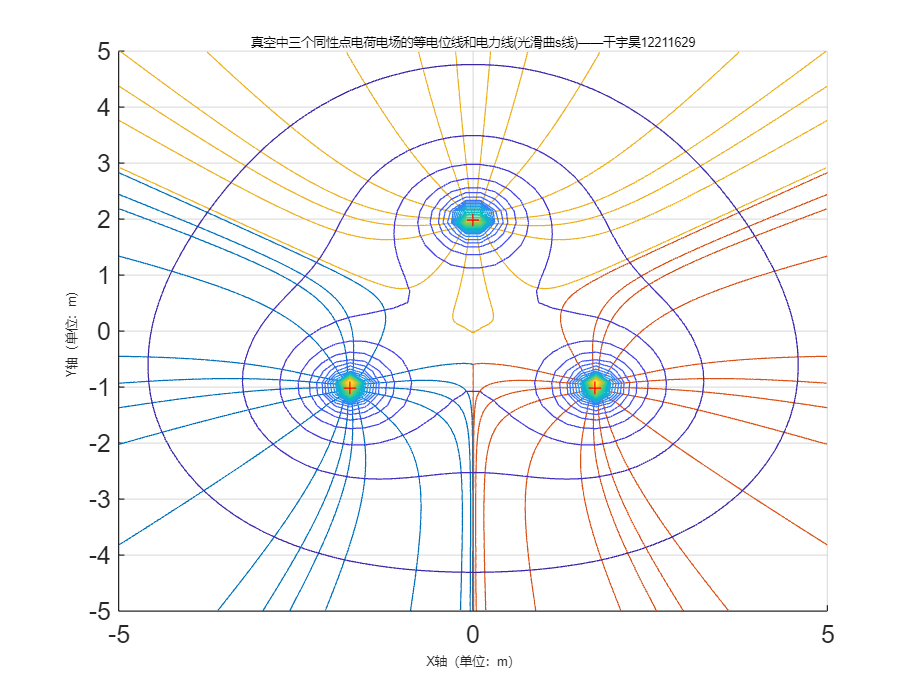

[Ex,Ey] = gradient(-V);%计算场域各点的电场强度的两个分量
del_theta = 20;%设置相邻电力线间的角度差;
theta = (0:del_theta:360).*pi/180;%生成电力线的弧度值;
xs1 = -sqrt(3)+0.1*cos(theta);%生成电力线起点的x轴坐标;
ys1 = -1-0.1*sin(theta);%生成电力线起点的y轴坐标;
xs2 = sqrt(3)+0.1*cos(theta);%生成电力线起点的x轴坐标;
ys2 = -1-0.1*sin(theta);%生成电力线起点的y轴坐标;
xs3 = 0.1*cos(theta);%生成电力线起点的x轴坐标;
ys3 = 2+0.1*sin(theta);%生成电力线起点的y轴坐标;
figure;
streamline(X,Y,Ex,Ey,xs1,ys1);
streamline(X,Y,Ex,Ey,xs2,ys2);
streamline(X,Y,Ex,Ey,xs3,ys3);
grid on;
hold on;
contour(X,Y,V,Veq);
hold on;
plot(-sqrt(3),-1,'+r','MarkerSize',5);%画出电荷1
hold on;
plot(sqrt(3),-1,'+r','MarkerSize',5);%画出电荷2
hold on;
plot(0,2,'+r','MarkerSize',5);%画出电荷3
title('真空中三个同性点电荷电场的等电位线和电力线(光滑曲s线)——干宇昊12211629','FontSize',5);
xlabel('X轴（单位：m）','FontSize',5);%绘出X轴标注
ylabel('Y轴（单位：m）','FontSize',5);%绘出Y轴标注

Analysis: 120 degree rotation symmetry of equipotential line

5）Plot the distribution of equipotential lines and electric field lines (represented by normalized arrows) in the field

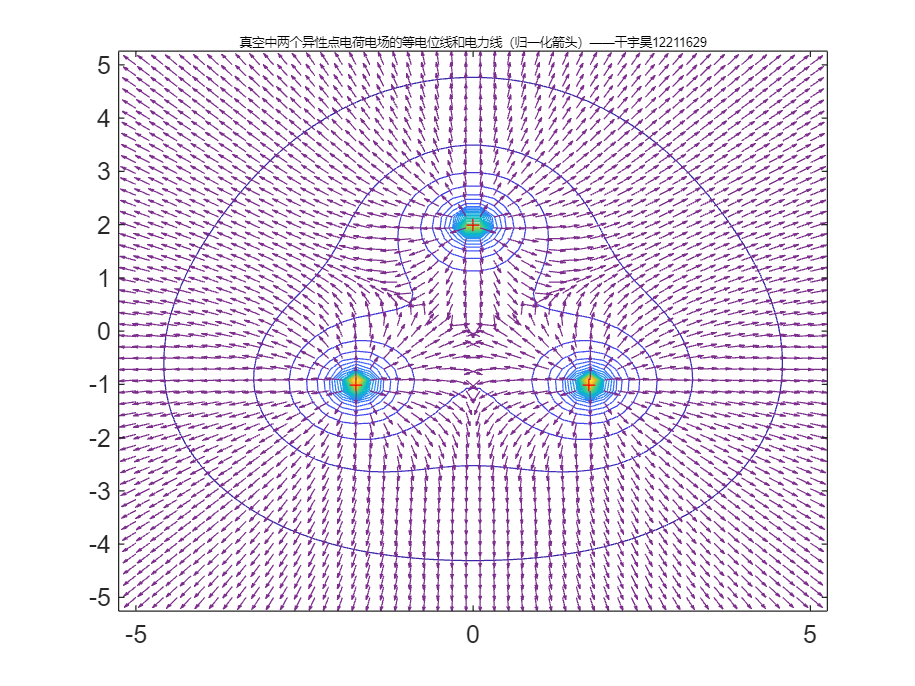

E = sqrt(Ex.^2+Ey.^2);%计算场域各点的电场强度的幅值
Ex = Ex./E;%归一化电场强度值（即使各点场强幅值为1
Ey = Ey./E;
figure;
contour(X,Y,V,Veq);
hold on;
plot(-sqrt(3),-1,'+r','MarkerSize',5);%画出电荷1
hold on;
plot(sqrt(3),-1,'+r','MarkerSize',5);%画出电荷2
hold on;
plot(0,2,'+r','MarkerSize',5);%画出电荷3
hold on;
quiver(X,Y,Ex,Ey);%用归一化箭头表示场域各点电场强度的方向
title('真空中两个异性点电荷电场的等电位线和电力线（归一化箭头）——干宇昊12211629','FontSize',5);

Analysis: The electric field lines spread out around the center of the three charges and gradually sparse

**Four:**

**Conclusion:** Through Matlab visualization of the electric potential, equipotential lines, and electric fields around point charges, a clear and intuitive understanding of the theoretical concepts is achieved, providing viable technical solutions for related problems.